# Model Predictive Control

Optimal control is a method to use model predictions to plan an optimized future trajectory for time-varying systems. It is often referred to as Model Predictive Control (MPC) or Dynamic Optimization. The following is an introductory video from the [**Dynamic Optimization Course**](https://apmonitor.com/do)

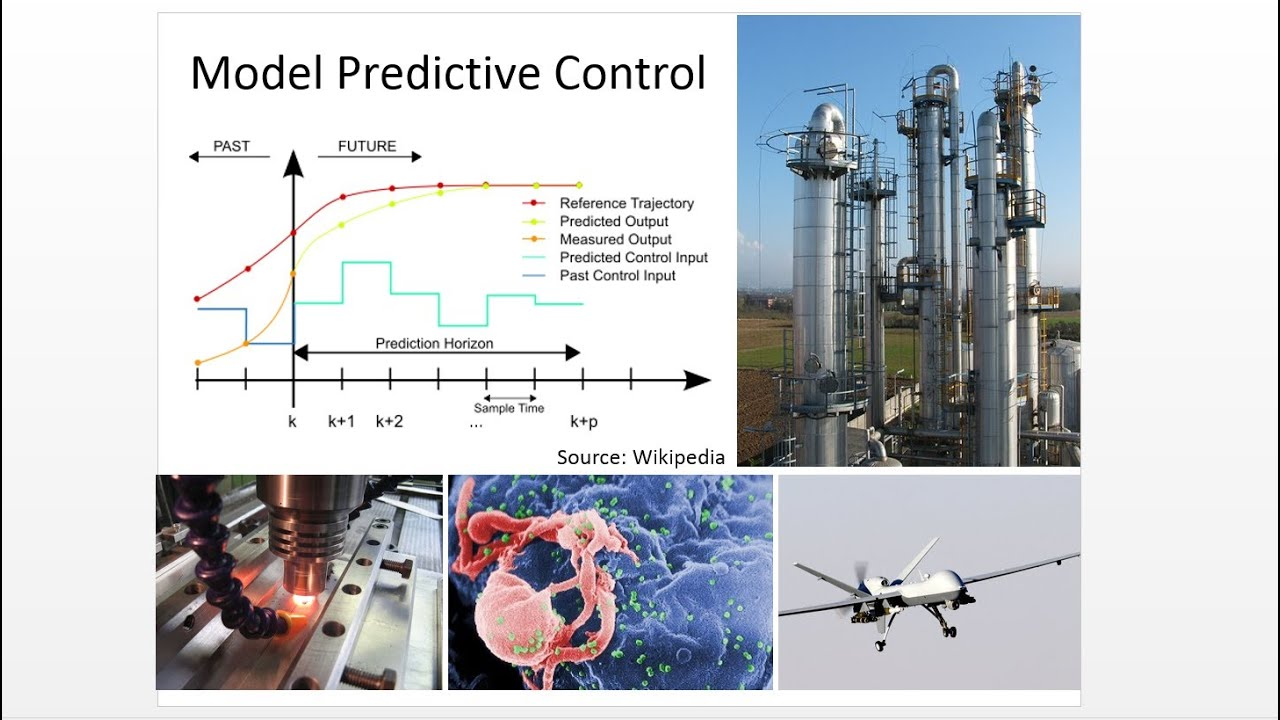

### [View Lecture](https://www.youtube.com/watch?v=YHAA-uXhI0E&feature=emb_imp_woyt)

A method to solve dynamic control problems is by numerically integrating the dynamic model at discrete time intervals, much like measuring a physical system at particular time points. The numerical solution is compared to a desired trajectory and the difference is minimized by adjustable parameters in the model that may change at every time step. The first control action is taken and then the entire process is repeated at the next time instance. The process is repeated because objective targets may change or updated measurements may have adjusted parameter or state estimates.

Model predictive control has a number of manipulated variable (MV) and controlled variable (CV) tuning constants. The tuning constants are terms in the optimization objective function that can be adjusted to achieve a desired application performance.

As the tuning parameters are adjusted, the MPC profile is updated to reveal the effect of the change. Additional information on MPC tuning parameters is available at [**MPC Controller Tuning**](https://apmonitor.com/do/index.php/Main/ControllerTuning) as part of the Dynamic Optimization course. There is also documentation available at [**Overview of APMonitor**](https://apmonitor.com/wiki/index.php/Main/DBS) and [**Gekko Options**](https://gekko.readthedocs.io/en/latest/global.html). These are useful for configuring a model predictive control solution such as the vehicle model predictive control exercise.

Below is an example of MPC used to control a suspended weight that behaves like a pendulum:

## Exercise

**Objective:** Design a model predictive controller for an overhead crane with a pendulum mass. Meet specific control objectives by tuning the controller and using the state space model of the crane system. Simulate and optimize the pendulum system with an adjustable overhead cart. *Estimated time: 2 hours.*

A pendulum is described by the following dynamic equations:

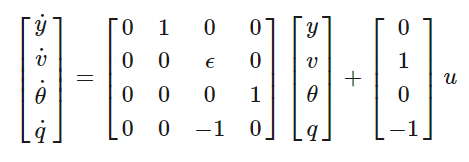

where $m_1=10$ is the mass of the cart, $m_2=1$ is the mass of the item carried, $\epsilon$ is $\frac{m_2}{(m_1+m_2}$, *y* is the position of the overhead cart, $v$ is the velocity of the overhead cart, $\theta$ is the angle of the pendulum relative to the cart, and *q* is the rate of angle change2.

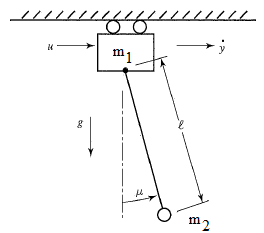

The objective of the controller is to adjust the force on the cart to move the pendulum mass to a new final position. Ensure that initial and final velocities and angles of the pendulum are zero. The position of the pendulum mass is initially at -1 and it is desired to move it to the new position of 0 within 6.2 seconds. Demonstrate controller performance with changes in the pendulum position and that the final pendulum mass remains at the final position without oscillation. How does the solution change if the mass of the item carried is increased to $m_2=5$?

*Please note for the code to work properly, the current working directory must be the directory that contains this live script as well as the .apm file.*

clear all; close all; clc
addpath('apm')

% server and application
s = 'http://byu.apmonitor.com';
a = 'crane_pendulum';

% clear application
apm(s,a,'clear all');

% load model and data file
apm_load(s,a,'pendulum.apm');
csv_load(s,a,'pendulum.csv');

% option: dynamic control mode
apm_option(s,a,'nlc.imode',6);

% classify: manipulated variable
apm_info(s,a,'MV','u');

% option: let optimizer use MV to minimize objective
apm_option(s,a,'u.status',1);

% solve
output = apm(s,a,'solve');
disp(output)

apm 72.48.20.151_crane_pendulum <br><pre> ----------------------------------------------------------------
 APMonitor, Version 1.0.1
 APMonitor Optimization Suite
 ----------------------------------------------------------------
 
 
 --------- APM Model Size ------------
 Each time step contains
   Objects      :            0
   Constants    :            0
   Variables    :            8
   Intermediates:            1
   Connections  :            0
   Equations    :            7
   Residuals    :            6
 
 Number of state variables:            910
 Number of total equations: -          840
 Number of slack variables: -            0
 ---------------------------------------
 Degrees of freedom       :             70
 
 ----------------------------------------------
 Dynamic Control with APOPT Solver
 ----------------------------------------------
 
 Iter    Objective  Convergence
    0  1.21283E+00  0.00000E+00
    1  4.22065E-03  3.22889E-10
    2  1.75879E-03  3.33277E-02
    3  1

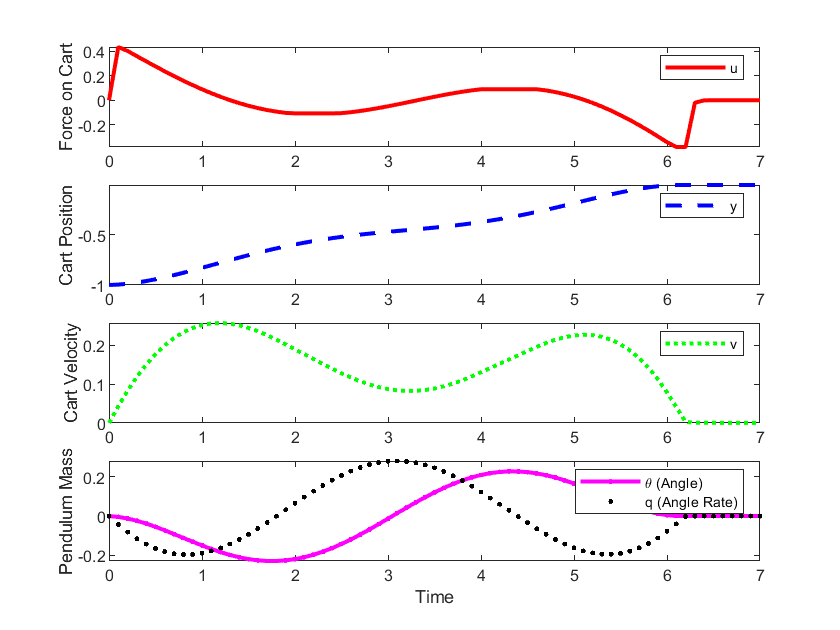


% retrieve results
y = apm_sol(s,a);
z = y.x;

figure(1)
subplot(4,1,1)
plot(z.time,z.u,'r-','LineWidth',2)
ylabel('Force on Cart')
legend('u')
axis tight

subplot(4,1,2)
plot(z.time,z.y,'b--','LineWidth',2)
ylabel('Cart Position')
legend('y')
axis tight

subplot(4,1,3)
plot(z.time,z.v,'g:','LineWidth',2)
ylabel('Cart Velocity')
legend('v')
axis tight

subplot(4,1,4)
plot(z.time,z.theta,'m.-','LineWidth',2)
hold on
plot(z.time,z.q,'k.','LineWidth',2)
ylabel('Pendulum Mass')
legend('\theta (Angle)','q (Angle Rate)')
axis tight
xlabel('Time')